# Example: MHKiT-MATLAB Wave Module

The following example runs an application of the [MHKiT wave module](https://mhkit-software.github.io/MHKiT/mhkit-matlab/api.wave.html) to 1) generate a capture length matrix, 2) calculate MAEP, and 3) plot the scatter diagrams.

## Load NDBC Data 

We can use MHKiT to load data downloaded from [https://www.ndbc.noaa.gov](https://www.ndbc.noaa.gov/).

relative_file_name = 'data/wave/data.txt';
current_dir = fileparts(matlab.desktop.editor.getActiveFilename);
full_file_name = fullfile(current_dir, relative_file_name);
% height
ndbc_data = read_NDBC_file(full_file_name);

disp(ndbc_data)

     spectrum: [47×743 double]
    frequency: [47×1 double]
         time: [01-Jan-2018 00:40:00    01-Jan-2018 01:40:00    01-Jan-2018 02:40:00    01-Jan-2018 03:40:00    …    ]



## Compute Wave Metrics

We will now use MHKiT to compute the significant wave height, energy period, and energy flux.

% Compute the energy periods from the NDBC spectra data 
Te = energy_period(ndbc_data);
disp(Te)

    7.4587
    7.6824
    7.4983
    7.6762
    7.6695
    7.4872
    7.1609
    7.0988
    6.4084
    6.6875
    7.1311
    7.9223
    8.7329
   10.5890
   10.7495
   11.5639
   11.7032
   12.7885
   13.3933
   13.5416
   13.6975
   13.4058
   13.2554
   14.0710
   14.2076
   13.5765
   13.5911
   13.3964
   12.5708
   12.8860
   12.0561
   11.9063
   11.4389
   11.8633
   11.4712
   11.1367
   11.8808
   11.0509
   11.3901
   11.2406
   11.1560
   11.1039
   11.5390
   10.9961
   11.1551
   11.1352
   11.5514
   11.7073
   11.4691
   11.6870
   11.6822
   11.0037
   10.8002
   11.0819
   10.2768
   11.1203
   11.0551
   11.9920
   12.0477
   12.0479
   12.0368
   12.5881
   12.5354
   13.1829
   12.7431
   12.6762
   12.9947
   12.8486
   12.8892
   12.9858
   13.2110
   13.2718
   13.7024
   13.0189
   13.9925
   13.7476
   14.0039
   14.1794
   13.3190
   13.5117
   13.5267
   12.9721
   12.8560
   12.9100
   13.2160
   12.2412
   12.5926
   12.3947
   12.7596
   12.7317
   12.3590

% Compute the significant wave height from the NDBC spectra data 
Hm0 = significant_wave_height(ndbc_data);
disp(Hm0)

    0.9396
    1.0014
    0.9248
    0.9625
    0.9899
    0.9077
    0.8270
    0.8229
    0.7579
    0.7362
    0.6946
    0.7164
    0.7673
    0.7702
    0.8136
    0.9248
    0.9474
    1.1393
    1.3787
    1.4231
    1.5012
    1.4957
    1.6174
    1.7519
    2.0416
    1.4796
    1.6752
    1.9991
    1.5020
    1.7231
    1.6358
    1.6565
    1.6547
    1.9734
    1.8632
    1.7776
    2.2054
    1.5430
    1.9860
    1.7727
    1.8487
    1.7260
    2.0250
    1.6200
    1.5547
    1.5036
    1.5085
    1.7589
    1.6725
    1.7937
    1.9764
    2.1123
    2.0405
    2.3157
    2.0473
    2.0640
    1.9839
    2.1994
    2.4058
    2.0717
    2.1667
    2.2680
    2.2764
    2.6078
    2.4926
    2.5988
    2.9700
    3.0042
    2.6976
    2.8703
    2.4405
    2.8508
    3.1804
    2.8305
    3.1774
    3.1907
    3.2499
    3.3094
    2.6992
    2.6945
    2.7209
    2.6319
    2.5705
    2.5706
    3.1439
    2.5672
    2.7081
    2.5694
    2.5015
    2.8454
    2.5059

% Set water depth to 60 m
h = 60;                                                  

% Compute the energy flux  from the NDBC spectra data and water depth
J = energy_flux(ndbc_data,h);
disp(J)

   1.0e+05 *

    0.0335
    0.0392
    0.0328
    0.0366
    0.0387
    0.0318
    0.0255
    0.0252
    0.0192
    0.0191
    0.0183
    0.0220
    0.0284
    0.0354
    0.0402
    0.0564
    0.0599
    0.0957
    0.1471
    0.1588
    0.1790
    0.1733
    0.2000
    0.2511
    0.3445
    0.1713
    0.2199
    0.3084
    0.1613
    0.2191
    0.1822
    0.1840
    0.1752
    0.2603
    0.2225
    0.1955
    0.3243
    0.1456
    0.2506
    0.1972
    0.2115
    0.1839
    0.2647
    0.1603
    0.1501
    0.1399
    0.1467
    0.2020
    0.1779
    0.2096
    0.2539
    0.2690
    0.2457
    0.3275
    0.2330
    0.2622
    0.2400
    0.3258
    0.3916
    0.2903
    0.3161
    0.3662
    0.3675
    0.5114
    0.4494
    0.4858
    0.6530
    0.6572
    0.5328
    0.6077
    0.4481
    0.6162
    0.7964
    0.5937
    0.8101
    0.8034
    0.8505
    0.8926
    0.5560
    0.5629
    0.5749
    0.5132
    0.4845
    0.4862
    0.7499
    0.4569
    0.5243
    0.4628
    0.4563
    0.5

## Generate Random Power Data

For demonstration purposes, this example uses synthetic power data generated from statistical distributions. In a real application, the user would provide power values from a WEC.

% generating 1,000,000 random power values
Power = randi([40,200], 743,1); 
disp(Power)

   171
   185
    60
   187
   141
    55
    84
   128
   194
   195
    65
   196
   194
   118
   168
    62
   107
   187
   167
   194
   145
    45
   176
   190
   149
   161
   159
   103
   145
    67
   153
    45
    84
    47
    55
   172
   151
    91
   192
    45
   110
   101
   163
   168
    70
   118
   111
   144
   154
   161
    84
   149
   145
    66
    59
   120
   194
    94
   134
    76
   160
    81
   121
   152
   183
   194
   128
    62
    64
    81
   175
    80
   171
    79
   189
    96
    71
    80
   139
   116
    96
   173
   134
   128
   187
    86
   161
   161
   101
   131
    52
    48
   125
   165
   190
    60
   131
   115
    41
    94
    66
   167
    90
   125
    66
   136
    82
   145
   150
   160
   112
    53
    76
   187
    64
   172
   126
   200
    52
   111
    57
   194
    40
   164
   171
   179
    53
   104
    81
   168
   109
   186
    69
    82
    63
    61
   179
   133
   128
    63
   177
   140
    96

## Capture Length Matrices

The following operations create capture length matrices, as specified by the IEC/TS 62600-100. But first, we need to calculate capture length and define bin centers. The mean capture length matrix is printed below. Keep in mind that this data has been artificially generated, so it may not be representative of what a real-world scatter diagram would look like.

% calculating capture length with power and wave flux in vectors
L = capture_length(Power,J) 

L =     0.0510
    0.0472
    0.0183
    0.0510
    0.0365
    0.0173
    0.0329
    0.0507
    0.1009
    0.1023



% Need to set our Hm0 and Te bins for the capture length matrix
Hm0_bins = -0.5:0.5:max(fix(Hm0))+0.5; % Input is min, max, and n indecies for vector
Hm0_bins = Hm0_bins+0.25 ; 
Te_bins = 0:1:max(fix(Te));
Te_bins = Te_bins+0.5;

% Calculate the necessary capture length matrices for each statistic based
% on IEC/TS 62600-100
clmat.mean = capture_length_matrix(Hm0,Te,L,"mean",Hm0_bins,Te_bins);
clmat.std = capture_length_matrix(Hm0,Te,L,"std",Hm0_bins,Te_bins);
clmat.count = capture_length_matrix(Hm0,Te,L,"count",Hm0_bins,Te_bins);
clmat.min = capture_length_matrix(Hm0,Te,L,"min",Hm0_bins,Te_bins);
clmat.max = capture_length_matrix(Hm0,Te,L,"max",Hm0_bins,Te_bins);

% Calculate the frequency matrix for convenience 
clmat.freq = capture_length_matrix(Hm0,Te,L,"frequency",Hm0_bins,Te_bins);

Let's see what the data in the mean matrix looks like. Keep in mind that this data has been artificially generated, so it may not be representative of what a real-world scatter diagram would look like.

disp(clmat.mean.values)

  Columns 1 through 14

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN    0.1016    0.0425    0.0683       NaN    0.0376    0.0144       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0472       NaN       NaN       NaN       NaN    0.0195    0.0089
       NaN       NaN       NaN       NaN       NaN       NaN    0.0098    0.0108    0.0069    0.0032    0.0075    0.0057    0.0062    0.0069
       NaN       NaN       NaN       NaN       NaN       NaN    0.0036    0.0025    0.0051    0.0042    0.0039    0.0035    0.0032    0.0039
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0038    0.0033    0.0029    0.0024    0.0022

## Power Matrices

As specified in IEC/TS 62600-100, the power matrix is generated from the capture length matrix and wave energy flux matrix, as shown below

% Create wave energy flux matrix using mean
jmat = wave_energy_flux_matrix(Hm0,Te,J,"mean",Hm0_bins,Te_bins);

% Create power matrix using mean
avg_power_mat = power_matrix(clmat.mean, jmat);

% Create power matrix using standard deviation
std_power_mat = power_matrix(clmat.std, jmat);

The `capture_length_matrix` function can also be used as an arbitrary scatter plot generator. To do this, simply pass a different array in the place of capture length (L). For example, while not specified by the IEC standards, if the user doesn't have the omnidirectional wave flux, the average power matrix could hypothetically be generated in the following manner:

avgpowmat_not_standard = capture_length_matrix(Hm0,Te,Power,'mean',Hm0_bins,Te_bins);

## MAEP

There are two ways to calculate mean annual energy production (MAEP). One is from capture length and wave energy flux matrices, the other is from time series data, as shown below.

% Calculate maep from timeseries
maep_timeseries = mean_annual_energy_production_timeseries(L,J)

maep_timeseries = 1.0474e+06

% Calculate maep from matrix
maep_matrix = mean_annual_energy_production_matrix(clmat.mean, jmat , clmat.freq)

maep_matrix = 1.0589e+06

## Graphics

The graphics function `plot_matrix` can be used to visualize results. It is important to note that the plotting function assumes the step size between bins to be linear.

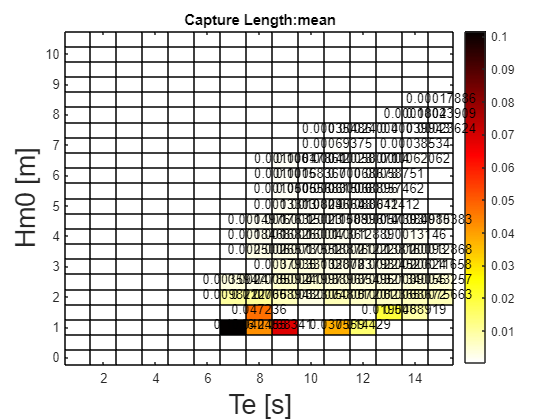

% Plot the capture length matrix
p1 = plot_matrix(clmat.mean,"Capture Length");